!) Determine the values of r at which the 1-cycle and the 2-cycle are super stable.

%FOR Cycle 1 refer written one 

syms x r

p = r*(1-x)*(1-r*x+r*x^2) - 1 

$$p = -r\,\left(x-1\right)\,\left(r\,x^{2}-r\,x+1\right)-1$$


roots = solve(p,x,"MaxDegree",3)

$$roots = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}+\frac{2}{3}\\ \frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{\sigma_{1}}{2}+\frac{2}{3}-\frac{\sqrt{3}\,\left(\frac{\sigma_{2}}{\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2}\\ \frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{\sigma_{1}}{2}+\frac{2}{3}+\frac{\sqrt{3}\,\left(\frac{\sigma_{2}}{\sigma_{1}}+\sigma_{1}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{r-1}{2\,r^{2}}-\frac{r^{2}+r}{3\,r^{2}}+\sqrt{{\sigma_{2}}^{3}+{\left(\frac{r-1}{2\,r^{2}}-\frac{r^{2}+r}{3\,r^{2}}+\frac{8}{27}\right)}^{2}}+\frac{8}{27}\right)}^{1/3}\\ \sigma_{2}=\frac{r^{2}+r}{3\,r^{2}}-\frac{4}{9} \end{array}$$


pdash = diff(p)

$$pdash = r\,\left(r-2\,r\,x\right)\,\left(x-1\right)-r\,\left(r\,x^{2}-r\,x+1\right)$$

2) Consider the logistic map xk+1 = r xk (1 − xk) , 0 ≤ x ≤ 1 . (a) Determine the values of r at which the 1-cycle and the 2-cycle are super stable. (b) Next consider the special case of r = 4, i.e., the map xk+1 = 4 xk (1 − xk) , 0 ≤ x ≤ 1 . What are the various types of solutions possible for this special case? Hint: You might like to use the substitution xk = sin2 (θk) with an appropriate interval for θk for uniqueness of the mapping, and obtain the map for θk as θk+1 = g (θk) . If you proceed along these lines, also sketch the map for θk. Calculate the Lyapunov exponent to justify presence of chaotic solutions if any.

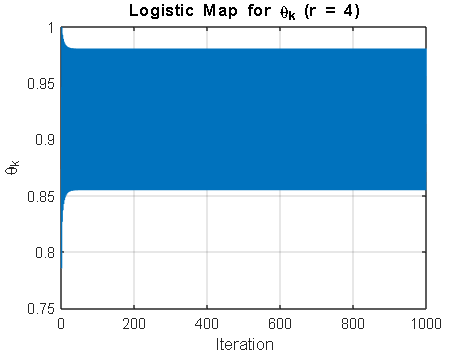

% Define the logistic map function
g = @(theta) 4 * sin(theta).^2 .* cos(theta).^2;

% Initial condition
theta0 = pi / 4; % Choose some initial angle

% Number of iterations
n_iterations = 1000;

% Preallocate array to store trajectory
theta_traj = zeros(1, n_iterations);

% Initialize trajectory
theta_traj(1) = theta0;

% Iterate the logistic map
for i = 2:n_iterations
    theta_traj(i) = g(theta_traj(i-1));
end

% Plot the map
figure;
plot(1:n_iterations, theta_traj);
xlabel('Iteration');
ylabel('\theta_k');
title('Logistic Map for \theta_k (r = 4)');
grid on;


% Calculate Lyapunov exponent
delta_theta = abs(diff(theta_traj));
lyapunov_exp = mean(log(abs(delta_theta(2:end) ./ delta_theta(1:end-1))));
fprintf('Lyapunov Exponent: %f\n', lyapunov_exp);

Lyapunov Exponent: -0.000534
